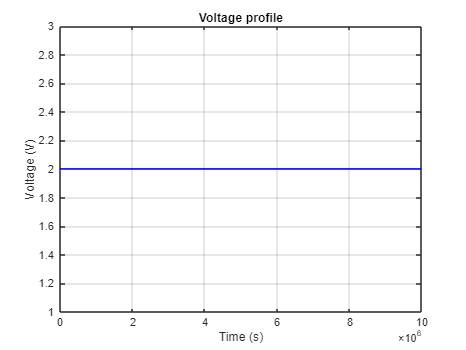

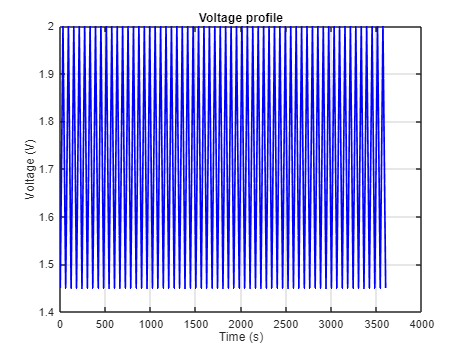

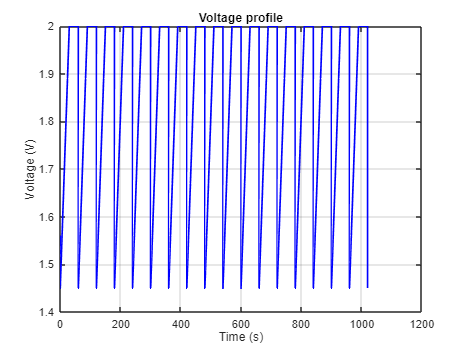

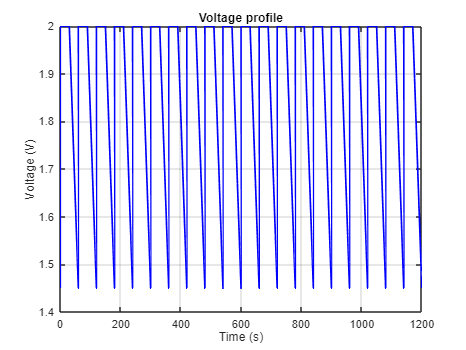

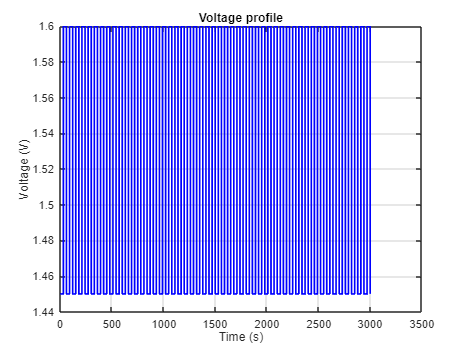

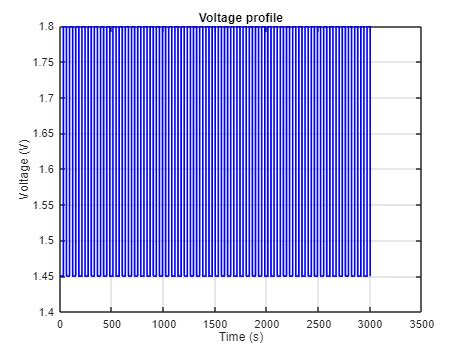

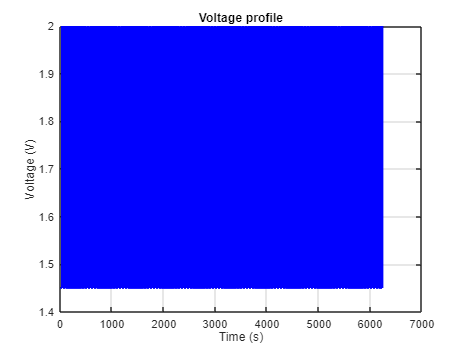

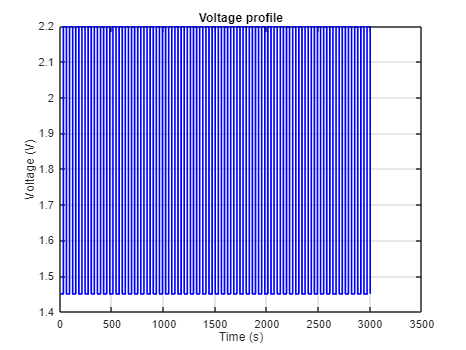

archivos = {
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\Hold.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\triangle.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\sawtooth_down.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\sawtooth_up.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_16V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_18V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_22V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_25V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_30s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_20s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_10s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\solar.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\wind.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\N115_NREL_2.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\N212_NREL_2.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\N117_NREL_2_2.xlsx'  
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\N117_NREL_2_2_5.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\N117_NREL_2_3.xlsx'  
};

%% ================== CALCULO DE METRICAS ==================
dynamism2_all = [];
for i = 1:length(archivos)
    filePath = archivos{i};
    [d1, d2, d3] = funtzio(filePath);
    dynamism2_all = [dynamism2_all; d2];    
end

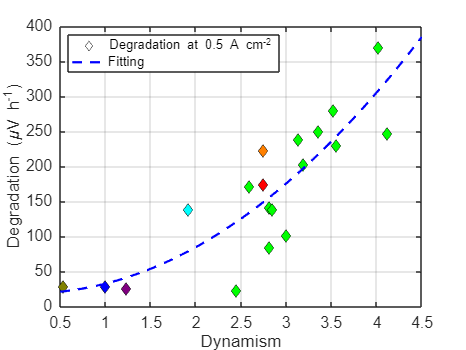

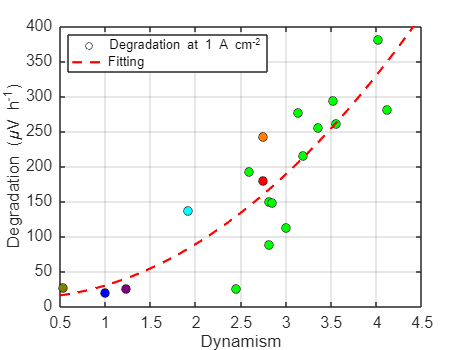

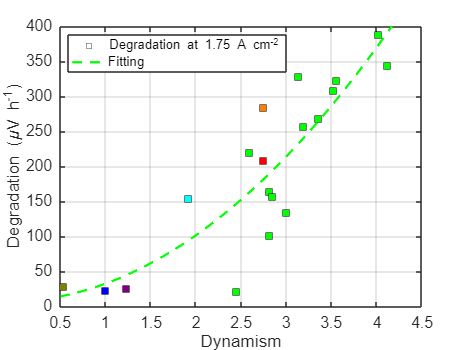


limiteak = [2, 1.05, 10, 0.05, -0.05];
[n_filas, ~] = size(dynamism2_all);
metric2_all = zeros(n_filas, 6);
max_val_col1 = max(dynamism2_all(:, 1), [], 'omitnan');

for i = 1:n_filas
    divisiones = zeros(1,5);
    valor_actual = dynamism2_all(i, 1);
    divisiones(1) = (valor_actual - 1.45) / (limiteak(1) - 1.45);
    divisiones(1) = min(max(divisiones(1),0),1);
    divisiones([2 4 5]) = dynamism2_all(i, [2 4 5]) ./ limiteak([2 4 5]);
    divisiones(3) = limiteak(3) / dynamism2_all(i,3);
    divisiones(divisiones > 1) = 1;
    metric2_all(i,1:5) = divisiones;
    metric2_all(i,6) = sum(divisiones,'omitnan');
end
metric2 = metric2_all(:,6);

%% ================== DATOS DE DEGRADACION ==================
degradation_05 = [28.3809524, 138.5714, 174.6667, 222.095, 22.8572, 84.7619, ...
         202.8571, 229.5238, 246.667, 249.5238, 279.4286, 369.5238, ...
         25.4629, 27.777, 140.95, 171.43, 139, 100.95, 238.1 ];
degradation_1 = [19.4285714, 137.5238, 180.381, 242.2857, 26.0952, 88.7619, ...
          215.619, 261.7142, 281.1428, 255.619, 293.5238, 380.5714, ...
          26.0185, 27.639,150, 192.38, 148.57, 112.38, 276.19];
degradation_175 = [23.4285714, 154.2857,208.5714, 284, 21.9048, 101.9048, ...
          256.19, 322.8571, 343.8095, 267.619, 307.619, 388, 25.6944,...
          28.472, 163.81, 219.05, 156.19, 133.33, 327.62];

tipo_senal = {'Hold', 'Triangle', 'Sawtooth down', 'Sawtooth up', ...
              'Square', 'Square', 'Square', 'Square', ...
              'Square', 'Square', 'Square', 'Square', ...
              'Solar', 'Wind', 'Square', 'Square', 'Square', 'Square', 'Square'};

color_map = containers.Map( ...
    {'Hold', 'Sawtooth down', 'Sawtooth up', 'Solar', 'Square', 'Triangle', 'Wind'}, ...
    {[0 0 1], [1 0 0], [1 0.5 0], [0.5 0 0.5], [0 1 0], [0 1 1], [0.5 0.5 0]});

degradaciones = {degradation_05, degradation_1, degradation_175};
densidades = {'0.5 A/cm²','1 A/cm²','1.75 A/cm²'};
marcadores = {'d','o','s'};
tipos = unique(tipo_senal);
colores_densidad = {[0 0 1], [1 0 0], [0 1 0]};

%% ================== GRAFICAS SEPARADAS CON AJUSTES ==================
for j = 1:3
    figure; hold on;

    % === Puntos experimentales ===
    for i = 1:length(tipos)
        tipo = tipos{i};
        idx = strcmp(tipo_senal, tipo);
        c = color_map(tipo);
        scatter(metric2(idx), degradaciones{j}(idx), 60, marcadores{j}, ...
            'MarkerEdgeColor','k','MarkerFaceColor',c, 'HandleVisibility','off');
    end

    % === Ajuste polinómico ===
    valid = ~isnan(metric2) & ~isnan(degradaciones{j}');
    p = polyfit(metric2(valid), degradaciones{j}(valid), 2);
    x_fit = linspace(0.5,4.5,200);
    y_fit = polyval(p, x_fit);
    h_fit = plot(x_fit, y_fit, '--', 'Color', colores_densidad{j}, ...
                 'LineWidth', 2, 'DisplayName', ['Fitting ']);

    xlabel('Dynamism','FontSize',16);
    ylabel('Degradation (\muV h^{-1})','FontSize',16);
    grid on; box on; set(gca,'FontSize',14);
    xlim([0.5 4.5]);
    ylim([0 400]);
    xticks(0.5:0.5:4.5); % Ticks cada 0.5
    yticks(0:50:400);
    if j == 1
        leg_marker = plot(NaN, NaN, marcadores{j}, 'MarkerEdgeColor','k', ...
                          'MarkerFaceColor','w', ...
                          'DisplayName','Degradation at 0.5 A cm^{-2}');
    elseif j == 2
        leg_marker = plot(NaN, NaN, marcadores{j}, 'MarkerEdgeColor','k', ...
                          'MarkerFaceColor','w', ...
                          'DisplayName','Degradation at 1 A cm^{-2}');
    else
        leg_marker = plot(NaN, NaN, marcadores{j}, 'MarkerEdgeColor','k', ...
                          'MarkerFaceColor','w', ...
                          'DisplayName','Degradation at 1.75 A cm^{-2}');
    end

    legend([leg_marker, h_fit], 'Location', 'Northwest','FontSize',12);
end

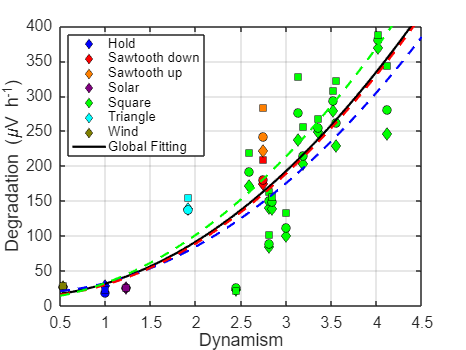


%% ================== FIGURA FINAL GLOBAL CON PUNTOS Y AJUSTES ==================
figure; hold on; set(gca,'FontSize',14);
h_scatter = gobjects(length(tipos),1);

% === Dibujar los puntos experimentales con sus colores ===
for i = 1:length(tipos)
    tipo = tipos{i};
    idx = strcmp(tipo_senal, tipo);
    c = color_map(tipo);
    h_scatter(i) = scatter(metric2(idx), degradation_05(idx), 60, 'd', ...
                           'MarkerEdgeColor','k','MarkerFaceColor',c,'DisplayName',tipo);
    scatter(metric2(idx), degradation_1(idx), 60, 'o', 'MarkerEdgeColor','k','MarkerFaceColor',c,'HandleVisibility','off');
    scatter(metric2(idx), degradation_175(idx), 60, 's', 'MarkerEdgeColor','k','MarkerFaceColor',c,'HandleVisibility','off');
end

% === Ajuste global polinómico ===
x_all = [metric2(~isnan(degradation_05)); metric2(~isnan(degradation_1)); metric2(~isnan(degradation_175))]; 
y_all = [degradation_05(~isnan(degradation_05))'; degradation_1(~isnan(degradation_1))'; degradation_175(~isnan(degradation_175))']; 
[p, S, mu] = polyfit(x_all, y_all, 2); 
x_fit = linspace(0.5, 4.5, 200);
y_fit = polyval(p, x_fit, S, mu); 
h_fit = plot(x_fit, y_fit, 'k-', 'LineWidth',2, 'DisplayName','Global Fitting');

% === Ajustes locales individuales por densidad ===
colores_densidad = {[0 0 1], [1 0 0], [0 1 0]};
estilos = {'--', '--', '--'};
degradaciones_list = {degradation_05, degradation_1, degradation_175};
densidades = {'0.5 A/cm²','1 A/cm²','1.75 A/cm²'};

for j = 1:3
    valid = ~isnan(metric2) & ~isnan(degradaciones_list{j}');
    p_local = polyfit(metric2(valid), degradaciones_list{j}(valid), 2);
    x_fit_local = linspace(0.5, 4.5, 200);
    y_fit_local = polyval(p_local, x_fit_local);
    plot(x_fit_local, y_fit_local, estilos{j}, 'Color', colores_densidad{j}, ...
         'LineWidth',2, 'DisplayName',['Fit ', densidades{j}]);
end

xlabel('Dynamism','FontSize',16);
ylabel('Degradation (\muV h^{-1})','FontSize',16);
legend([h_scatter; h_fit], 'Location','Northwest','FontSize',12);
grid on; box on;
xlim([0.5 4.5]);
ylim([0 400]);
xticks(0.5:0.5:4.5); % Ticks cada 0.5
yticks(0:50:400); % Ticks cada 0.5

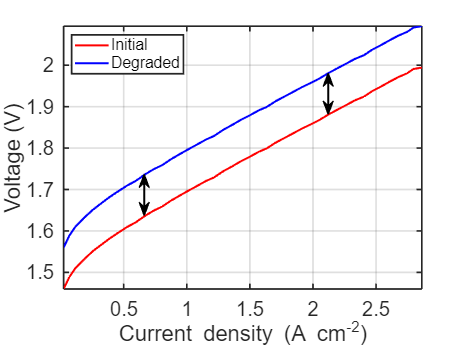


data=readmatrix('Polarizazio kurba.xlsx');
% Asignar columnas
x = data(:,1);
y2 = data(:,2); % Initial
y3 = data(:,3); % Degraded 1
y4 = data(:,4); % Degraded 2
y5 = data(:,5); % Degraded 3

%% === Función para dibujar flecha doble vertical en coordenadas reales ===
function draw_double_arrow(xval, y_low, y_high, color)
    ax = gca;
    pos = ax.Position;
    xlim_ = xlim(ax);
    ylim_ = ylim(ax);

    % Convertir coordenadas de datos a normalizadas
    x_norm = (xval - xlim_(1)) / (xlim_(2) - xlim_(1)) * pos(3) + pos(1);
    y1_norm = (y_low - ylim_(1)) / (ylim_(2) - ylim_(1)) * pos(4) + pos(2);
    y2_norm = (y_high - ylim_(1)) / (ylim_(2) - ylim_(1)) * pos(4) + pos(2);

    ah = annotation('doublearrow');
    ah.Color = color;
    ah.LineWidth = 1.8;
    ah.X = [x_norm x_norm];
    ah.Y = [y1_norm y2_norm];
end

%% === Función para obtener valores de flecha centrada entre curvas ===
function [y_low, y_high] = arrow_between_curves(x, curve_low, curve_high, xval)
    y_low = interp1(x, curve_low, xval);
    y_high = interp1(x, curve_high, xval);
end

%% === Dibujar gráfico con flechas centradas entre curvas ===
function plot_with_arrows(x, curve_init, curve_degraded)
    figure;
    plot(x, curve_init, 'r', 'LineWidth', 1.8); hold on;
    plot(x, curve_degraded, 'b', 'LineWidth', 1.8);

    x_pos1 = x(round(length(x)*0.25)); % posición izquierda
    x_pos2 = x(round(length(x)*0.75)); % posición derecha

    [y_low1, y_high1] = arrow_between_curves(x, curve_degraded, curve_init, x_pos1);
    [y_low2, y_high2] = arrow_between_curves(x, curve_degraded, curve_init, x_pos2);

    xlim tight;
    ylim tight;   % 🔹 Rango del eje Y

   % draw_double_arrow(x_pos1, y_low1, y_high1, 'k');
    %draw_double_arrow(x_pos2, y_low2, y_high2, 'k');

    xlabel('Current density (A cm^{-2})', 'FontSize', 16);
    ylabel('Voltage (V)', 'FontSize', 16);
    legend('Initial', 'Degraded', 'Location', 'Northwest', 'FontSize', 14);
    grid on; box on;

    ax = gca;
    ax.FontSize = 18;
    ax.LineWidth = 1.5;
    % 🔴 FORZAR actualización del layout del eje
    drawnow;

    % Posiciones de las flechas
    x_pos1 = x(round(length(x)*0.25));
    x_pos2 = x(round(length(x)*0.75));

    [y_low1, y_high1] = arrow_between_curves(x, curve_degraded, curve_init, x_pos1);
    [y_low2, y_high2] = arrow_between_curves(x, curve_degraded, curve_init, x_pos2);

    draw_double_arrow(x_pos1, y_low1, y_high1, 'k');
    draw_double_arrow(x_pos2, y_low2, y_high2, 'k');
end

%% === Graficar los tres casos ===
plot_with_arrows(x, y2, y3);

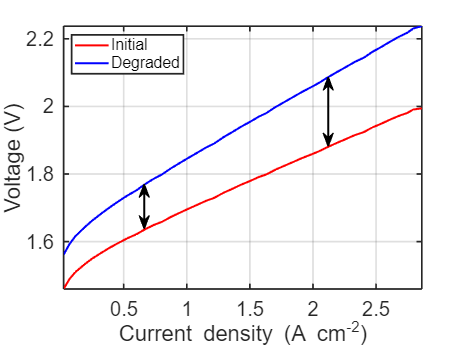

plot_with_arrows(x, y2, y4);

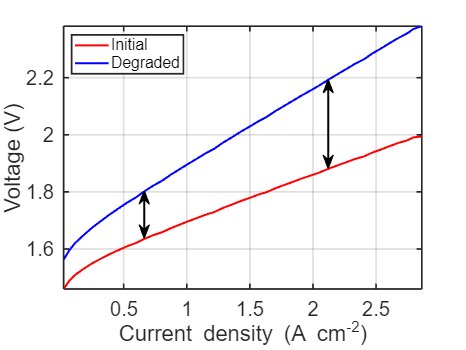

plot_with_arrows(x, y2, y5);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%





